%Run this first to generate a landscape to the desired specifications
% DO NOT run again if you want to keep the same landscape for further testing, only execute the code below
initialize (2, 30, 10, -10, 20, 0.20);


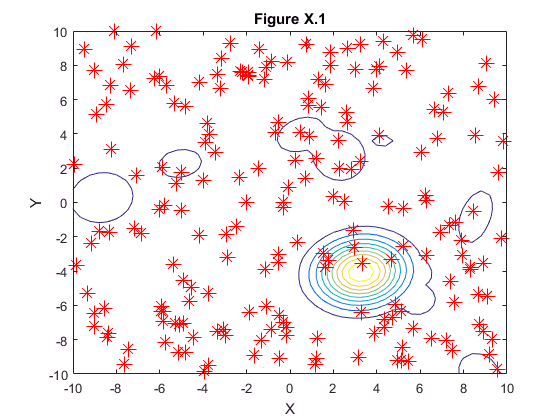

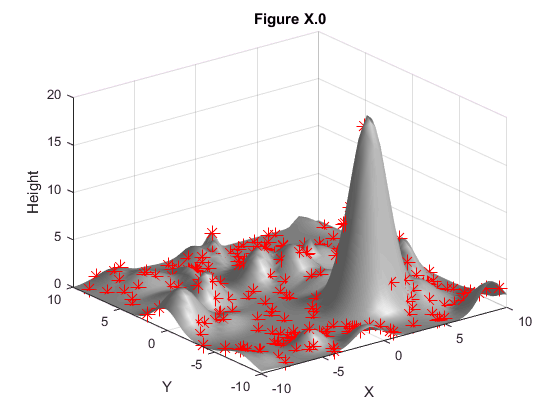

%ERROR: The fitness values can occasionally be too low for memory causing an error when executing this algorithim
%Simply executing the code again (or 2 or 3 (or 7) times) resolves the issue. 
%If persistent, try reducing the population size below

population = GenPop(200); % Create random population

plotlandscape (10, -10, 50, population); % Plot landscape and population (generation 1)


variation = zeros(50,2); %Preallocate memory to test variation in the population (change 50 to number of desired generations)

for i = 1:50 %Loops the number of generations desired
    
   
    how_fit = fitness(population); %Takes fitness of entire population
    
    maxfit = max(how_fit(:)); %Fitness of most fit point
    
    avg_fit = sum(how_fit)/length(how_fit); %Mean population fitness
    
    holder = std(population); %Takes standard deviation of the population in it's current generation
    variation(i,1) = holder(1,1);
    variation(i,2) = holder(1,2);
    
    plot(i, avg_fit, 'bo'); %Plot outputs
    plot(i,maxfit, 'rx');
    hold on
    title('Figure X.X: Max and Mean Fitness vs Generations'), xlabel('Generations'), ylabel('Fitness');
    legend('Maximum Fitness', 'Average Fitness');
    
    population = selectionFunct(population); %Pass population through genetic algorithim to generate new population
    
    
    i = i+1;
    

    

end

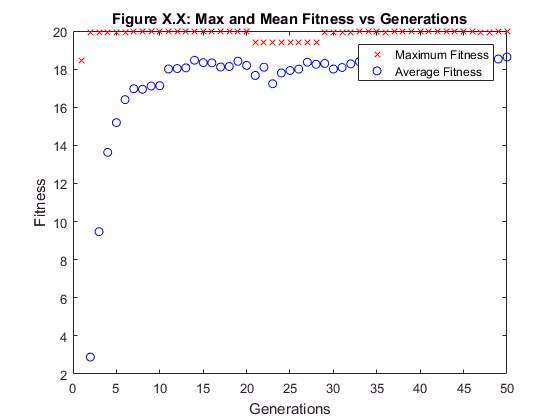

hold off

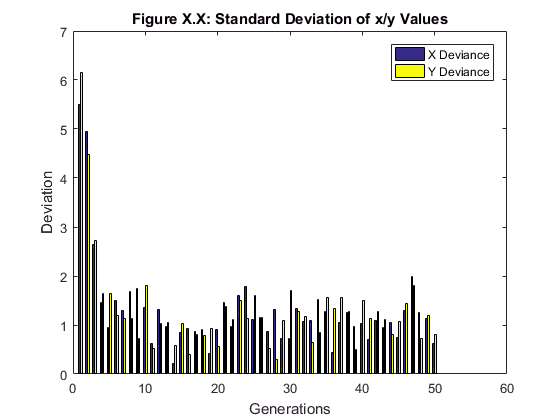


bar(variation) %plot variation
title('Figure X.X: Standard Deviation of x/y Values'), xlabel('Generations'), ylabel('Deviation')
legend('X Deviance', 'Y Deviance');

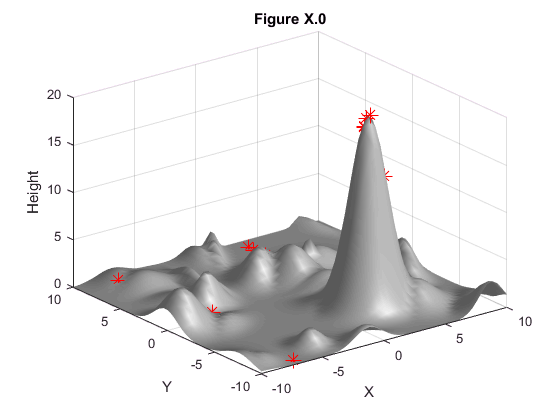

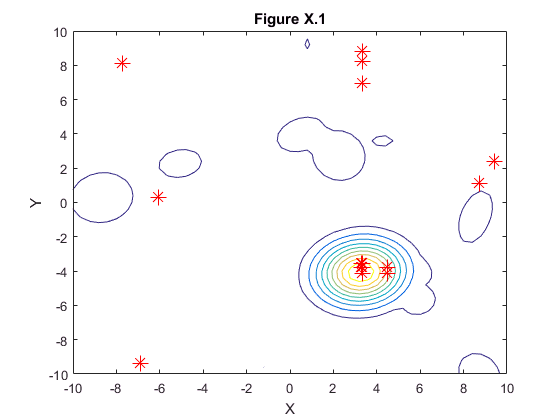

plotlandscape (10, -10, 50, population)


population %print final population to observe outliers (random mutations) and where points converge

population =     3.3421   -4.1362
    3.3421   -3.5713
    3.3421   -3.7711
    3.3421   -3.7711
    3.3421   -3.7711
    3.3421   -3.5713
    3.3421   -4.1362
    3.3421   -3.5713
    3.3421   -4.1362
    3.3421   -4.1362
